## Covid-19 Cough Sound Classification 

Cough sound along with pulmonary sounds is an important factor for prognosis in nearly all pulmonary diseases. Coughing is the excretion of the spasmodic air from the lungs. Type and severity of the coughing depends on the type of the disease and the damage it causes on the lungs.

Coronavirus disease (COVID-19) emerged first in Wuhan, a city of China, aggressively spread to all around the planet through small droplets from mouth and nose. The virus causes severe acute respiratory syndrome, patients with COVID-19 show various symptoms that includes fever, dry cough and difficulty in breathing. Coughing and fever are the common symptoms for the 80% of the patients. [[WHO Report](https://www.who.int/docs/default-source/coronaviruse/who-china-joint-mission-on-covid-19-final-report.pdf)]

One of the differentiable features of the cough is the sound of it, it is generated by the vibration of larger airways and laryngeal structures due to turbulent while expiration and these components are largely affecting the acoustic characteristics of the sound. Duration, quality, strength, character are important parameters of cough classification. 

Sars-Cov-2 virus harms the upper and lower respiratory tracts which specifically causes a dry cough, that is when the cough does not include mucus secretion. Coughing of people with COVID-19 can have a distant sound profile that can be differentiated from other coughing sounds, the different sound structure that can be measured and can be an important part of early prognosis. There are studies still going on that support this idea and coughing sounds of COVID-19 patients have been collected from all around the world. [[EPFL](https://coughvid.epfl.ch/)] [[University of Cambridge](https://www.covid-19-sounds.org/en/)] However, there hasn’t been any tool development yet to analyze the coughing sound of the patients with COVID-19. 

Here, our goal is to build up an algorithm that can classify the cough sound profile of COVID-19 patients and to use this analysis as an early prognosis tool.

### DATASET

The dataset is a collection of cough sounds that I have found online, there are 3 videos of COVID-19 patients:

[Covid 19 cough sound 1](https://www.youtube.com/watch?v=CMmsscVN-js) ( between 3-6'th seconds ) ve ( between 67-72'th seconds ) 

[Covid 19 cough sound 2](https://www.youtube.com/watch?v=GwFmk6PgmqI) ( between 8 - 12'th seconds)

[Covid 19 cough sound 3](https://www.youtube.com/watch?v=EZxcEljV6WA) ( In many intervals)

[Normal cough sounds](https://www.youtube.com/watch?v=i_hI3gVoRr0&t=63s) ( Several people, Video is dated May, 2018 so that none of the coughing sounds are stem from COVID-19 infection )

I extracted the cough sounds, I obtained 10 cough sounds with different duration from patients diagnosed COVID-19. Also, I obtained 10 normal cough sounds. In total, I collected 20 cough sounds with 60 seconds long.

### PREPARATION OF DATASET

Each cough sound recording session has a different duration. The sound signal were sampled at 44100 Hz and it has 16 bit sample resolution. In this study, every sound is divided into shorter windows that contain 1024 samples with a 25 percent overlap. Every window has a duration of 23 ms. Every window is labeled according to their types, COVID-19 or NORMAL. 

You can examine the dataset  and sounds with below code.

clc;
clear;

addpath('functions');
addpath('dataSets');

load('coughSet.mat')
sound(dataSet(6).SoundData,44100);

The dataset contains windowed cough sound is below.

load('windowedCoughSet.mat');

disp("length of windows: "+length(dataSet));

length of windows: 2201


The windowedCoughSet has contains 2201 labeled sound windows. 955 of them have labeled as COVID-19 (0) and 1246 of them have labeled as NORMAL (1) cough sounds.

### FEATURE CALCULATION

Seven features are calculated for each window in MATLAB. These features are selected among features used for classification adventitious sounds in respiratory sounds. For example, in this review paper [[Evaluation of features for classification of wheezes and normal respiratory sounds](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC6414007/)], an analysis was conducted to select best sound features (in spectral and time domain) among all features used to classify adventitious sounds among respiratory sounds so far. We select the best features according to this work and our experience. One of the team members has three years of experince on pulmonary sound analysis and wrote master thesis on classification on wheeze sounds.

The selected features:

- Kurtosis : Kurtosis gives a degree of how much the sample distribution fits the normal distribution.

- Renyi Entropies with order 1,2, and 3 : The information entropy is the measure of the average level of uncertainty inherent in the random variable's possible outcomes.

- Percentile Frequency Ratios (f25/f75, f25/f90, f50/f90, f50/f75) : The power spectral density shows the power of a signal as a function of frequency. f25, f50, f75, f90 are the frequencies which are 25 %, 50 %,75 % and 90 % of the total area under the normalized power spectral density function, respectively.

- Mean Crossing Irregularity:  Mean Crossing Irregularity is the regularity level of the intervals between zero crossings.

- AR Parameters (Yule-Walker -> LPC Paramters) : 

- Mell Frequency Cepstral Coefficients

- Tonality Index: Tonality index is a likelihood measure which decides if a sound signal segment is more tone-like or noise-like. 

% Kurtosis
dataSet=findKurtosis(dataSet);
disp("Kurtosis is finished.");

Kurtosis is finished.


% F25/F75
dataSet=Ratio_of_25_to_75(dataSet);
disp("F25/F75 is finished.");

F25/F75 is finished.


% F25/F90
dataSet=Ratio_of_25_to_90(dataSet);
disp("F25/F90 is finished.");

F25/F90 is finished.


% F50/F75
dataSet=Ratio_of_50_to_75(dataSet);
disp("F50/F75 is finished.");

F50/F75 is finished.


% F50/F90
dataSet=Ratio_of_50_to_90(dataSet);
disp("F50/F90 is finished.");

F50/F90 is finished.


% Mean Crossing Irregularity
dataSet=calcZeroCrIr(dataSet);
disp("Mean Crossing Irr is finished.");

Mean Crossing Irr is finished.


% AutoRegressive Parameters
dataSet = ArCalc(dataSet);
disp("AR parameters is finished.");

AR parameters is finished.


% Tonality Index
dataSet = tonalityCalc(dataSet);
disp("TonalityIndex is finished.");

TonalityIndex is finished.


% MFCC
dataSet = calcMFCC(dataSet);
disp("MFCC is finished.");

MFCC is finished.


% Renyi Entropy
dataSet = calcRenyiEntropy(dataSet);
disp("Renyi is finished.");

Renyi is finished.


disp("All is well");

All is well


More preperation:

% Training için hazırlama
T = struct2table(dataSet);
T = removevars(T, 'winSound');
T = removevars(T, 'winInds');
T = removevars(T, 'tonalMag');
T = removevars(T, 'phi_sav');
T = removevars(T, {'cm','energy','spectUnPred'});
T(1:2,:) = [];
T.TI = cell2mat(T.TI);
[row, col] = find(isnan(T{:,:}));
T(row,:) = [];
isCovid = [T.label];
T(isCovid == 1,12) = {'covid'};

T(isCovid == 0,12) = {'normal'};
T.Properties.VariableNames{12} = 'isCovid';
T = movevars(T, 'isCovid', 'Before', 'kurtosis');
T = splitvars(T, 'renyi');
T = splitvars(T, 'ArParams');
T.Properties.VariableNames{15} = 'Ar_Error';
T = splitvars(T, 'MFCCParams');

### CLASSIFIER SELECTION

I trained following classifiers:

- KNN (k = 9)

- Linear SVM (C=1)

- Poynomial SVM order 3 (C = 1, Kernel Scale = 4.7)

- Gaussian SVM (C = 1, Kernel Scale = 2.5)

- Maximum Likelihood with Multivariate Gaussian

- Binary Decision Tree (max numb of splits: 100 and Gini's diversity index)

The training data set is used with the five-fold cross-validation to determine the accurate performance of the classifiers. Because of the limited number of training data, cross-validation increases the performance of the classifier by the train more unseen samples. 

The Binary Decision Tree gave teh best  performance among other classifiers. You can see the details of the performance of this classifier below.

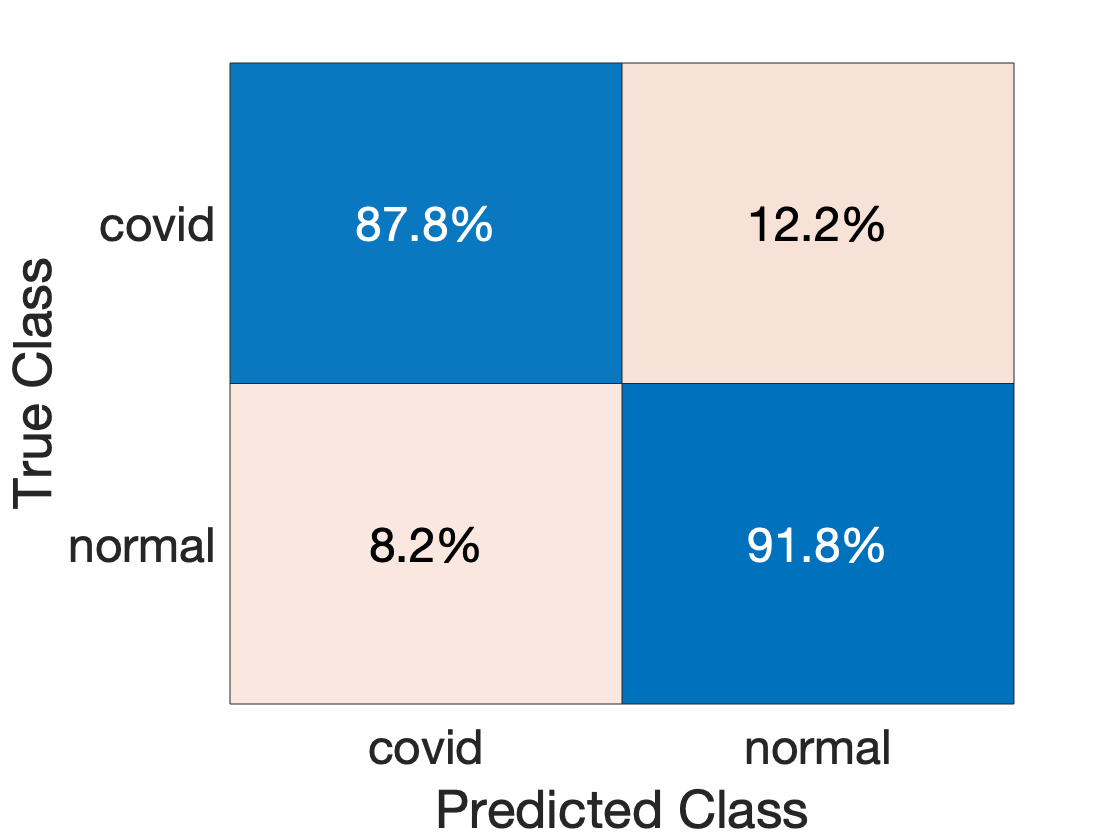

randoms = randperm(size(T,1));

X_label = T(:,2);
X = T(:,3:end);

X_train = X(randoms(1:size(T,1)),1:end);
X_train_label = table2cell( X_label(randoms(1:size(T,1)),1));

% Model
classificationTree = fitctree(...
    X_train, ...
    X_train_label, ...
    'SplitCriterion', 'gdi', ...
    'MaxNumSplits', 100, ...
    'Surrogate', 'off', ...
    'ClassNames', {'covid'; 'normal'});

% Performance
partitionedModel = crossval(classificationTree, 'KFold', 5);

[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

validationAccuracy = sum(strcmp(classificationTree.Y, validationPredictions))/length(validationPredictions);

confmat=confusionmat(classificationTree.Y,validationPredictions);

k = confusionchart(classificationTree.Y,validationPredictions,'Normalization','row-normalized','FontSize',24);
sortClasses(k,["covid","normal"])


disp("accuracy: "+validationAccuracy+"%");

accuracy: 0.90032%



TP = confmat(2,2);
FP = confmat(2,1);
FN = confmat(1,2);
TN = confmat(1,1);

disp("Sensivity: "+TP/(TP+FN)+"%");

Sensivity: 0.90569%


disp("Specificity: "+TN/(TN+FP)+"%");

Specificity: 0.89328%


disp("F1Ratio: "+2*TP/(2*TP+FN+FP));

F1Ratio: 0.91162


As you can see, algorithm predict the right labels with the accuracy of 90 %.  Sensivity (capability of labeling COVID-19 windows correctly among all COVID-19 windows )  is 88%. These results looks promising. On the other hand, we should not trust these results because the dataset which we created is small and not contains much data. We need more cough sounds to decide the best classifiers.

The below scatter graph shows the windows labeled as covid and windows labeled as normals according to MFCC 4 and MFCC 10. You can see the difference.

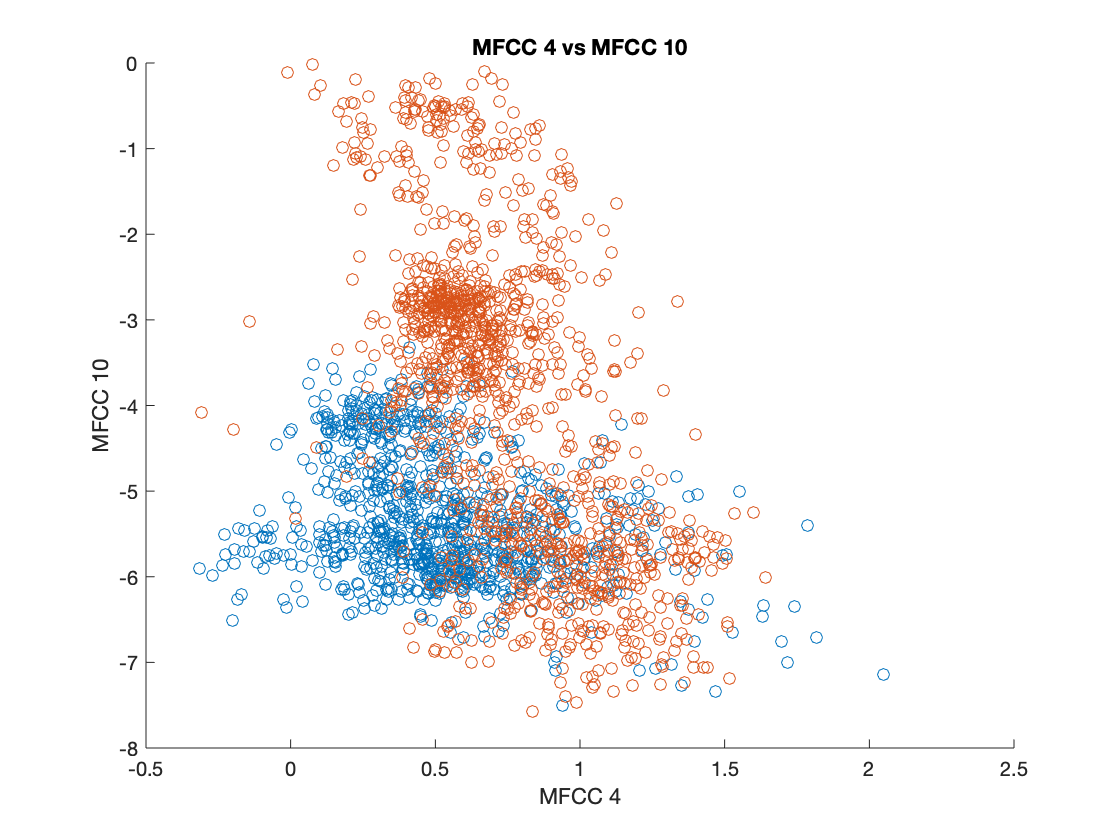

isCovid = [T.label]';
featureCovid = [T(isCovid == 1,:).MFCCParams_10 T(isCovid == 1,:).MFCCParams_4];
featureNonCovid = [T(isCovid == 0,:).MFCCParams_10 T(isCovid == 0,:).MFCCParams_4];

clf
scatter(featureCovid(:,1),featureCovid(:,2)); hold on; scatter(featureNonCovid(:,1),featureNonCovid(:,2))
title("MFCC 4 vs MFCC 10")
xlabel("MFCC 4");
ylabel("MFCC 10");

### BEST DISCRIMINATIVE FEATURE

In this part, the main aim is the reduce the number of features to find features with the best discriminatory ability. Forward feature selection is a well-known method to reduce data dimensionality. Reducing feature number increases the computational time, accuracy, and simplicity.

X_label = T(:,1);
X_train_label = X_label(randoms(1:size(T,1)),1);


%% FORWARD
opts = statset('display','iter');
 
classf = @(train_data, train_labels, test_data, test_labels)...
     sum(...
     predict(...
     fitctree(...
     train_data, ...
     train_labels, ...
     'SplitCriterion', 'gdi', ...
     'MaxNumSplits', 100, ...
     'Surrogate', 'off', ...
     'ClassNames', [0; 1])...
     ,test_data) ~= test_labels);
 
c = cvpartition(X_train_label{:,:},'k',5);
 
[fs, history] = sequentialfs(classf, X_train{:,:}, X_train_label{:,:}, 'cv', c, 'options', opts,'direction','forward');

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Step 1, added column 18, criterion value 0.252423
Step 2, added column 24, criterion value 0.185048
Step 3, added column 15, criterion value 0.140748
Step 4, added column 19, criterion value 0.119982
Step 5, added column 14, criterion value 0.0941394
Step 6, added column 17, criterion value 0.0909091
Step 7, added column 22, criterion value 0.0862944
Step 8, added column 26, criterion value 0.0816797
Step 9, added column 30, criterion value 0.0802953
Step 10, added column 16, criterion value 0.0770651
Step 11, added column 28, criterion value 0.0756807
Final columns included:  14 15 16 17 18 19 22 24 26 28 30 


As you can see from the results, Mell Frequency Cepstral Coefficient 4 and Mell Frequency Cepstral Coefficient 10 are the best discriminative features. The Binary Decision Tree reaches 89 percent accuracy rate with MFCC. Then, Tonality Index is second discriminative feature.

### DIAGNOSE **COVID**-**19** 

Diagnosing of covid-19 is one of the most important parts of this work. The pathway can be like following:

- Cough sound recorded for test is divided into shorter windows that contain 1024 samples with a 25 percent overlap.  (1024 samples and 25% overlap)

- Features are calculated for selected classifier.

- Then ML model predicts which windows contain covid-19 cough sounds.

- Then a treshold can be applied. For example, if the 70 % of windows of cough sound is labeled as  Covid-19, algorithm can say "You have 70 %  probability of being diagnosed Covid-19."

We did't do this part because we need more data to train classifier and diagnose Covid-19.

### WEB SITE

We created a web site to access more cough sounds and diagnostic data.

## Record your cough sound,

## help this research on Covid-19

[https://caglayan.github.io/covid19/#/en/](https://caglayan.github.io/covid19/#/en/)